# **Planeación de caminos para robots móviles en dos dimensiones.**

 En general los modelos para navegación (planeación + localización) y mapeo en robots móviles se puede clasificar de 3 maneras:

- Clásica: la planeación de movimientos se realiza al dividr el espacio de trabajo (o espacio de configuración) en secciones, dichas secciones se pueden convertir en un grafo y posteriormente, se realiza una busqueda para encontrar un camino libre. Previamente se requiere de un mapa con obstaculos

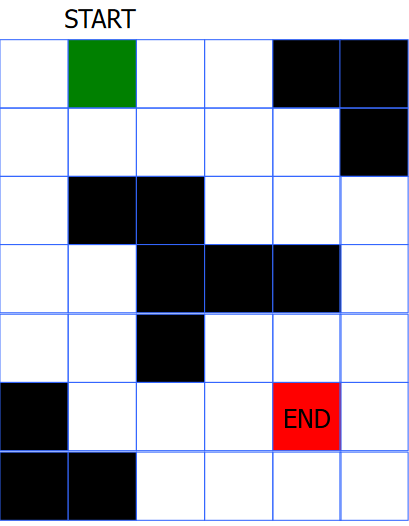     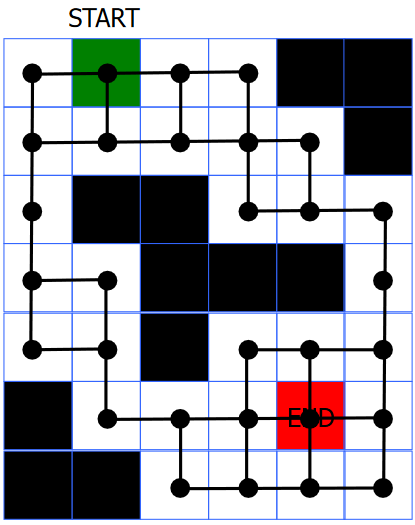

- Reactiva: la planeación no requiere formalmente de un mapa, los movimientos dependen unicamente de los estimulos actuales. Una excepción es la planeación por campos potenciales.

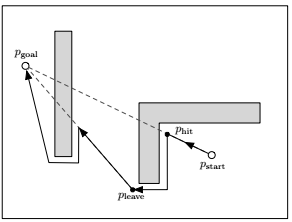  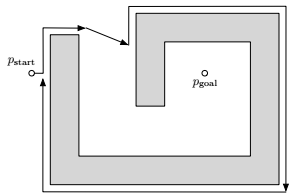

- Probabilistica: estos modelos son más utilizados para el mapeo y localización, incluso de manera simultanea (SLAM por sus siglas en inglés). Se utilizan modelos probabilisticos por grafos, como las cadenas ocultas de Markov o los filtros de Kalman para determinar posición tanto del robot como de los puntos de interes del mapa.

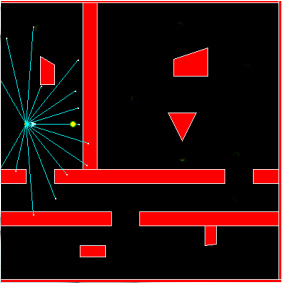     

## Espacio de configuración

Se piensa en el robot, ya sea móvil o un brazo, y los posibles obstaculos que se encuentran en el espacio de trabajo

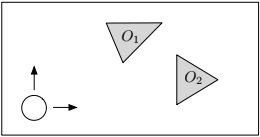  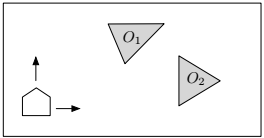 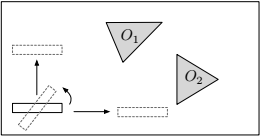 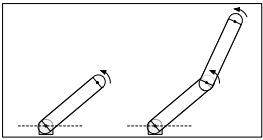

El espacio de configuración es una transformación del espacio de trabajo con coordenadas cartesianas $\left(x,y,z\right)$ a las a las coordenadas de juntas del robot $\left(q_1 ,q_2 \ldotp \ldotp \ldotp q_n \right)$

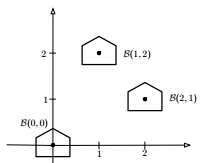     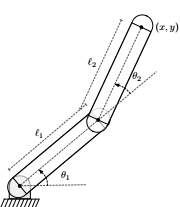   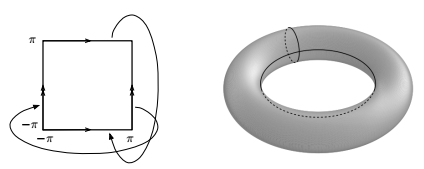

Contemplando los obstáculos se define el espacio de configuración libre, es decir los obstaculos se transforman en las coordenadas de juntas del robot, por ejemplo para un robot movil con forma cirucular o poligonal se pueden tener los siguientes espacios de configuración

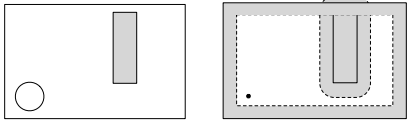   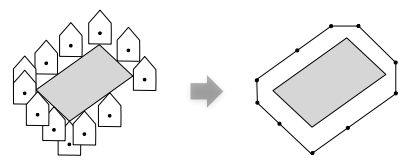

el objetivo es abstraer el movimiento del 

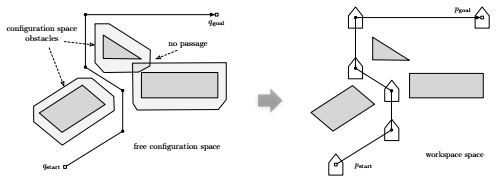

Para el caso de un brazo róbotico con 2 grados de libertad se observa lo siguiente:

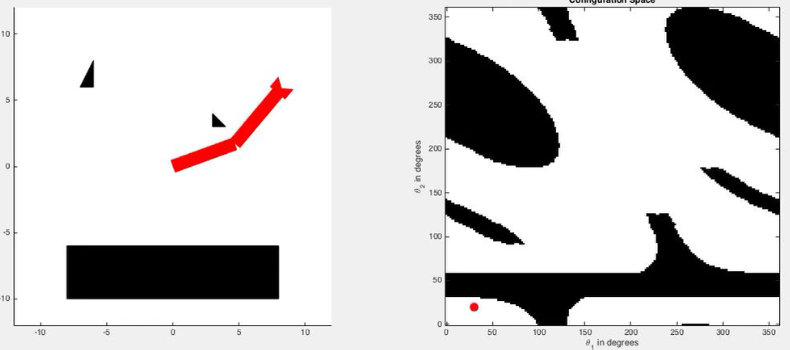

## Modelos clásicos o por búsqueda

Se utilizan grafos para modelar el camino libre de obstáculos, para encontrar el camino se utiliza busqueda en grafo, como puede ser Dijkstra o A*, como se determina el grafo depende del muestreo o divisición del espacio de configuración o espacio de trabajo (mapa). Algunos ejemplos son:

### Grafo de visivilidad (Equipo 3)

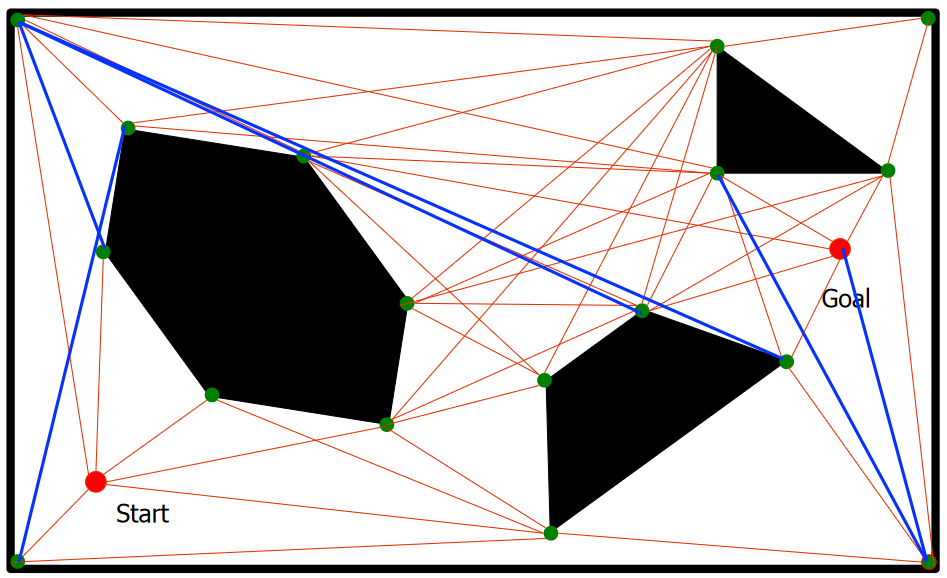

### Descomposición trapezoidal (Equipo 4)

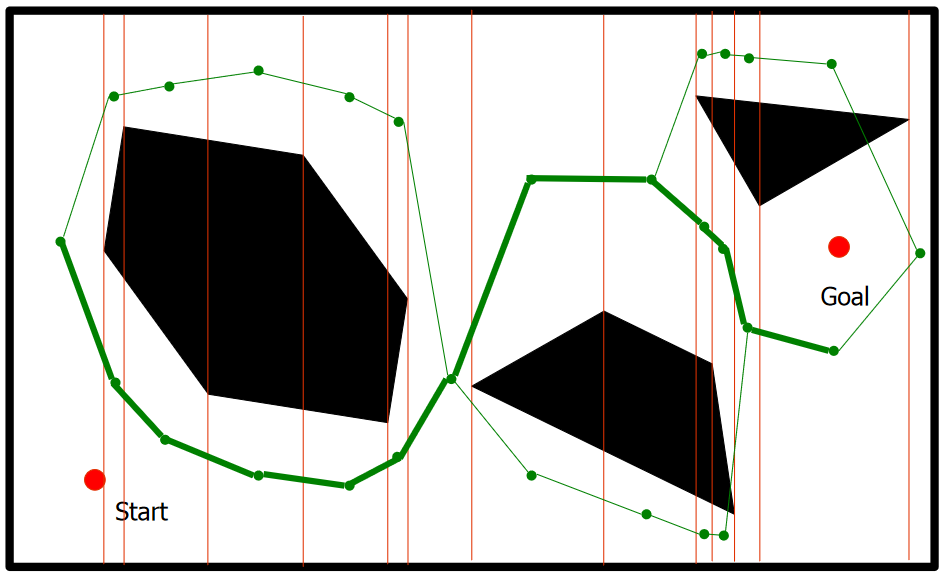

### Ruta probabilistica (Probabilistic Road Map PRM) (Equipo 5)

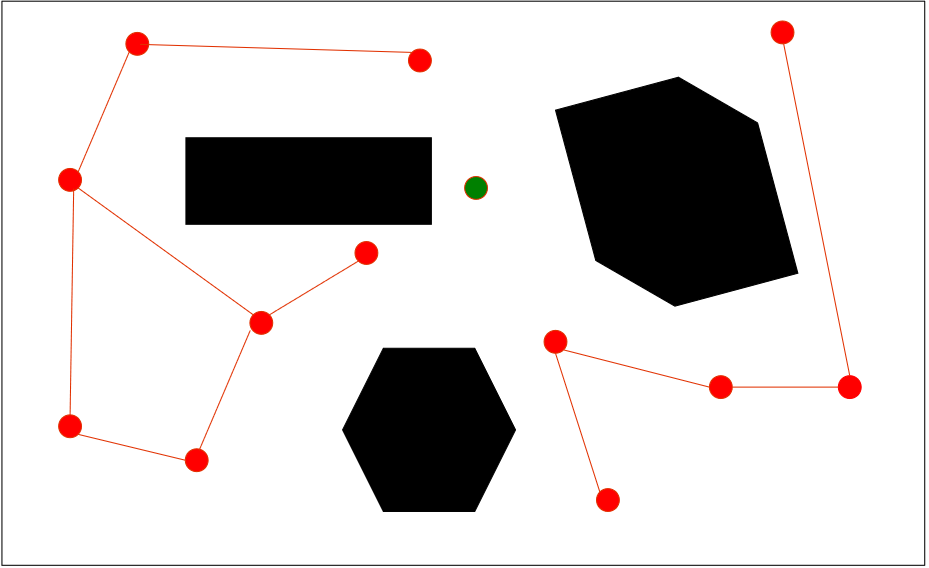    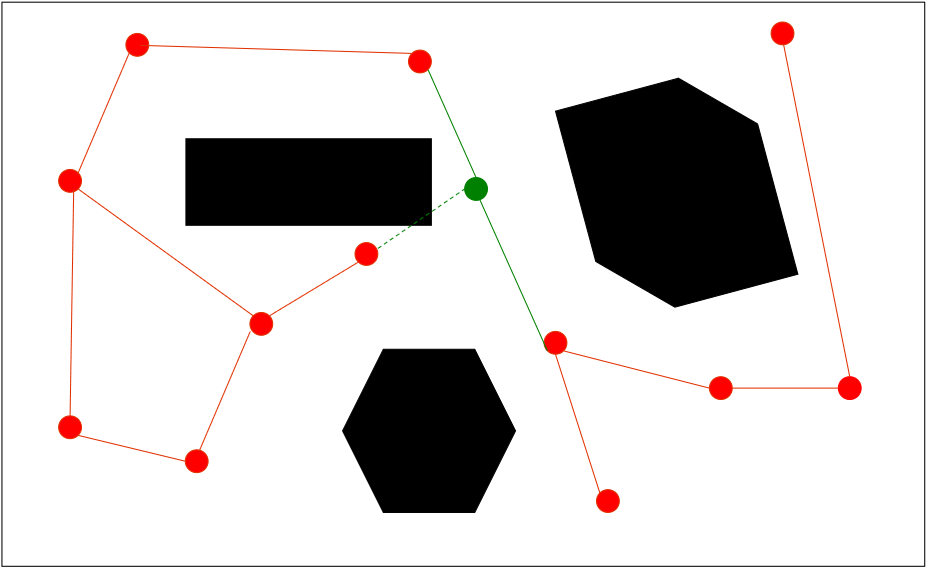

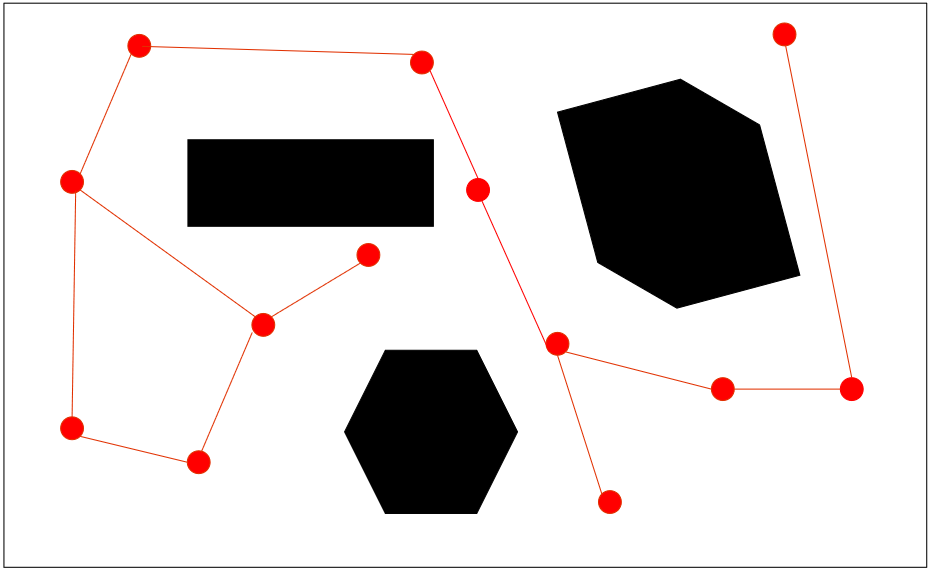

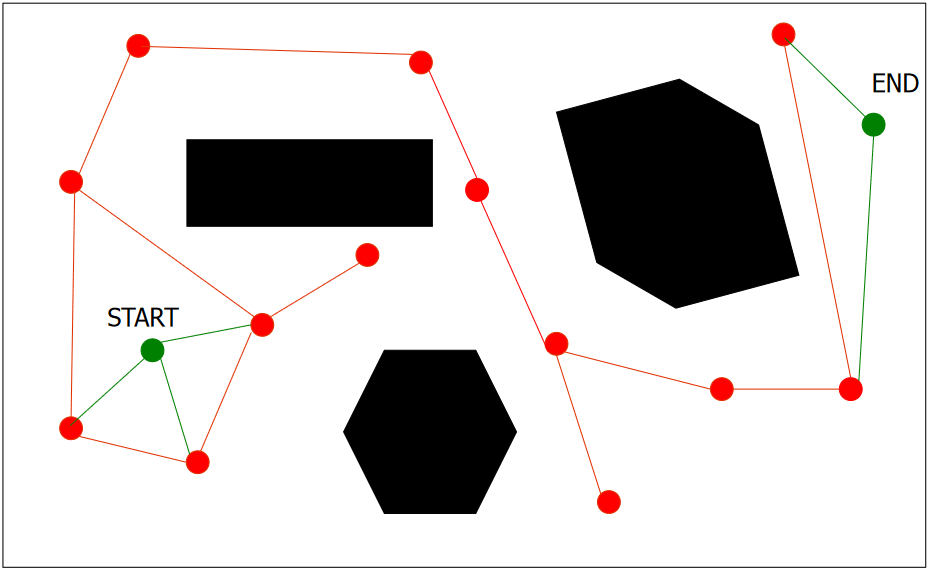

### Exploración rápida de árboles aleatorios (Rapid Road Map Tree RRT) ( Equipo 2)

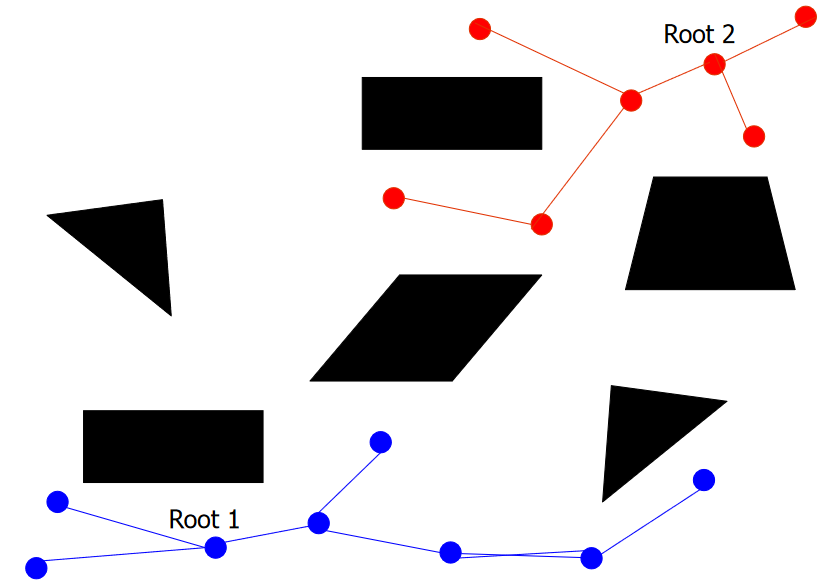

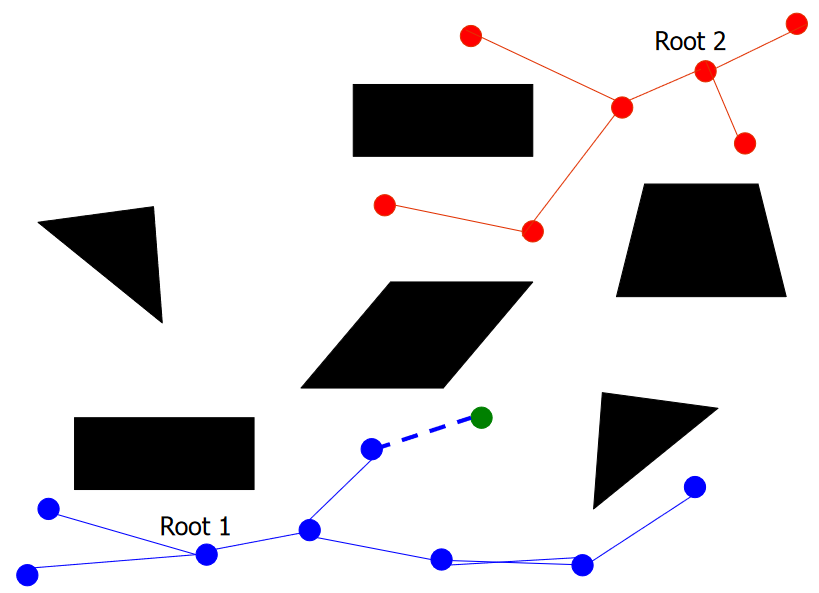

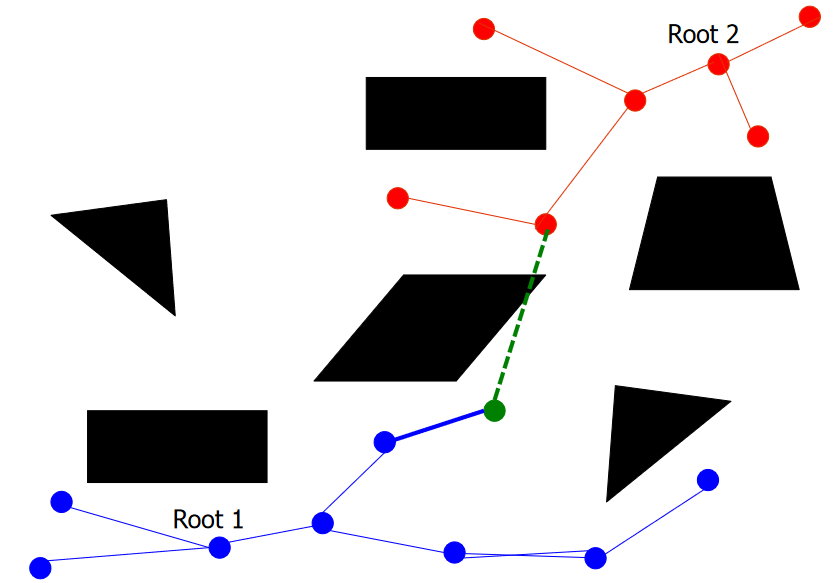

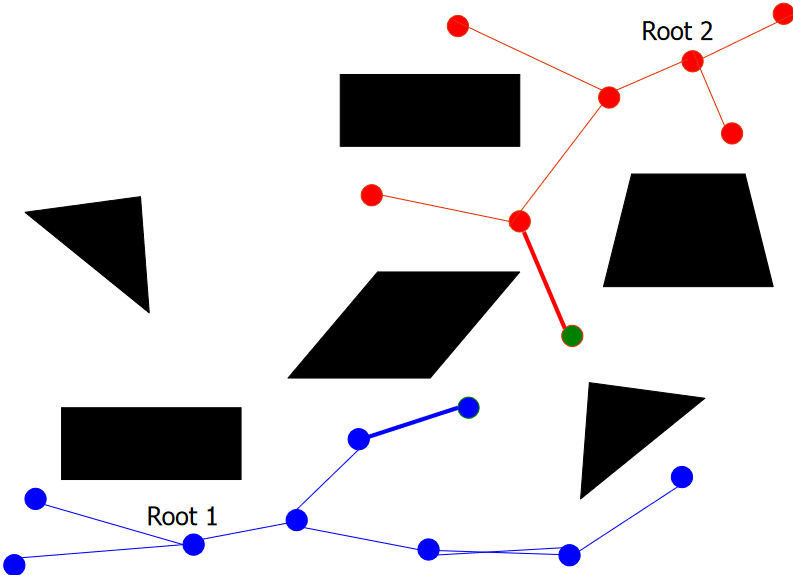

## Modelos reactivos y Campos Potenciales

### Modelos reactivos

Son algoritmos que se programan sin la necesidad de un mapa, su comportamiento generalmente se puede definir mediante una máquina de estados, por tanto tienen poca carga computacional. 

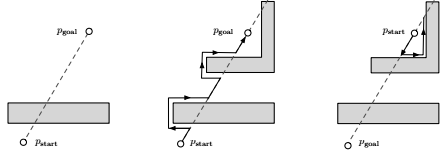

### Campos potenciales (Equipo 1)

Para el caso de los campos potenciales la carga computacional es baja, debido a se realiza un cálculo algebraico, pero es necesario conocer el mapa o espacio de trabajo de antemano. Los obstaculos se toman como un potencial repulsivo.

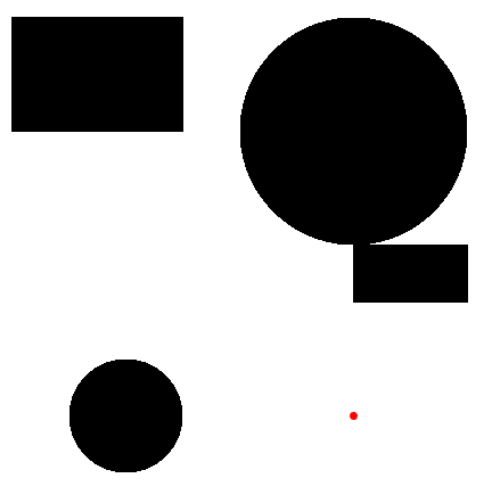   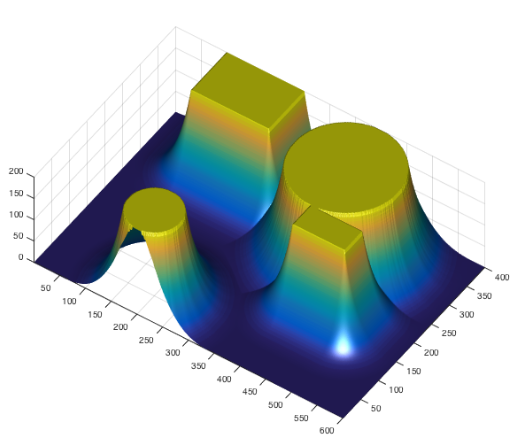

Teniendo en cuenta el inicio y fin de recorrido, como un potencial repulsivo y atractivo, respectivamente, y sumando del potencial de los obstaculos se obtiene lo siguiente

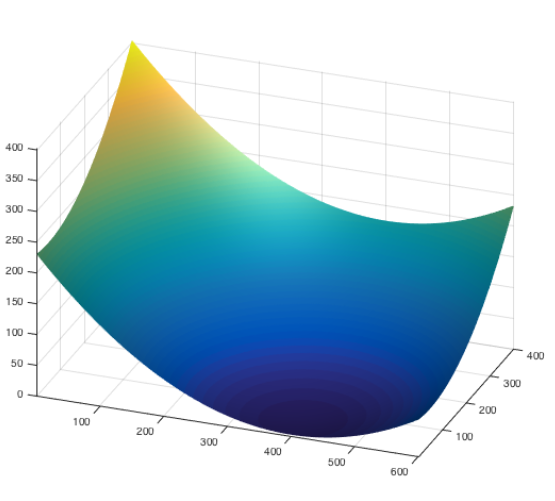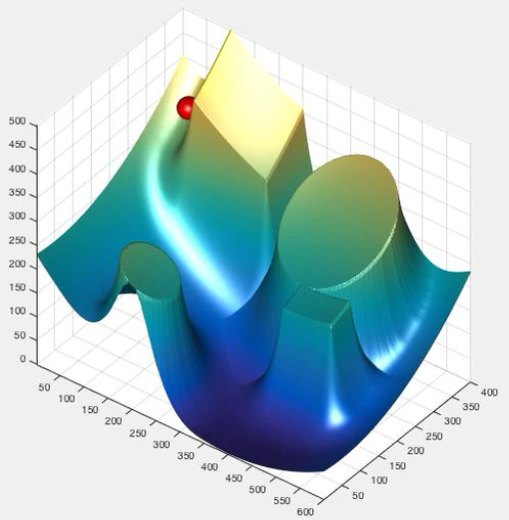

Otra forma de representarlo es mediante un potencial de flujo